clc;
clear;
close all;
load("data.mat");

% 步骤1: 数据预处理
Y = 2*y - 1;

% 归一化处理
X = normalize(X);

% 步骤二： 特征提取
numFeaturesToSelect = 15;
[SelectedFeatures, featureScores] = fscchi2(X, Y, 'N', numFeaturesToSelect);
selectedFeatures = SelectedFeatures (1:15);

% 输出选定的特征索引
disp('Selected Features:');

Selected Features:


disp(selectedFeatures);

     3     8    10    11    12    27    28    64    56    59    66    13    57     9    21



% 步骤3: 随机划分训练集和测试集
rng(42); % 设置随机数种子以确保可重复性
trainRatio = 0.7; % 训练集比例
testRatio = 0.3; % 测试集比例

numSamples = size(X, 1);
numTrainSamples = round(numSamples * trainRatio);
numTestSamples = numSamples - numTrainSamples;

permutedIndices = randperm(numSamples);
trainIndices = permutedIndices(1:numTrainSamples);
testIndices = permutedIndices(numTrainSamples+1:end);

trainX = X(trainIndices, :);
trainY = Y(trainIndices);
trainX = trainX(:,selectedFeatures);

testX = X(testIndices, :);
testY = Y(testIndices);
testX = testX(:,selectedFeatures);

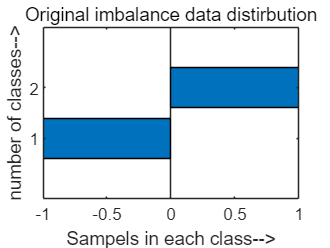

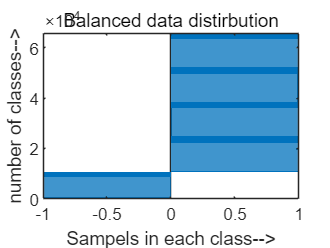

% 步骤4: 过采样平衡样本
allData = [trainX, trainY]; % 将原始特征矩阵和标签合并成一个矩阵
k = 5; % 设置k值
sortedIDX = sort(unique(Y)); % 获取排序后的标签类别
allData_smote = mySMOTE(allData, k, sortedIDX); % 使用mySMOTE函数进行过采样


% 提取过采样后的特征矩阵和标签
trainX = allData_smote(:, 1:end-1);
trainY = allData_smote(:, end);

% 步骤5: 使用SVM进行分类
svmModel = fitcecoc(trainX, trainY, 'Learners', templateSVM('KernelFunction', 'gaussian'));
svmLabels = predict(svmModel, testX);

% 步骤6: 评估分类结果
accuracy = sum(svmLabels == testY) / numel(testY);
disp('SVM Accuracy:');

SVM Accuracy:


disp(accuracy);

    0.8140




% 计算召回率
TP = sum(svmLabels == 1 & testY == 1);
FN = sum(svmLabels == -1 & testY == 1);
recall = TP / (TP + FN);
disp('Recall:');

Recall:


disp(recall);

    0.7674




svmLabels = predict(svmModel, X(:,selectedFeatures));

accuracy = sum(svmLabels == Y) / numel(Y);
disp('All SVM Accuracy:');

All SVM Accuracy:


disp(accuracy);

    0.8431




% 计算召回率
TP = sum(svmLabels == 1 & Y == 1);
FN = sum(svmLabels == -1 & Y == 1);
recall = TP / (TP + FN);
disp('All Recall:');

All Recall:


disp(recall);

    0.9243



function allData_smote = mySMOTE(allData, k,sortedIDX)
% mySMOTE  Synthetic Minority Oversampling Technique. A technique to
% generate synthetic samples as given in: https://www.jair.org/media/953/live-953-2037-jair.pdf
%   Usage:
%   X_smote = mySMOTE(X, N, k) 
%   
%   Inputs:
%   allData: Original dataset
%   k: number of nearest neighbors to consider while performing
%   augmentation
%   sortedIDX: sorted labels
% 
%   Outputs:
%   X_smote: augmented dataset containing original data as well.
%   
%   See also datasample, randsample
%% plot the bar plot for number of classes
figure
barh(sortedIDX)
ylabel('number of classes-->')
xlabel('Sampels in each class-->')
title('Original imbalance data distirbution')
%% number of each classes
labels=allData(:,end);
class=unique(sortedIDX);
for ii=1:numel(class)
    classNo(ii)=numel(find(labels==class(ii)));
end
%% required addon samples in each minority class
%add on samples will be calculated by taking the difference of each
%classSamples with highest number of class samples
[maximumSamples,sampleClass]=max(classNo); % number of maximum samples
for ii=1:numel(class)
    samplediff(ii)=maximumSamples-classNo(ii);
    N (ii) = ceil(samplediff(ii)/ 100);
    
end
%% oversample the minority classes
allData_smote=[];
for ii=1:numel(class)
    X=allData(labels==class(ii),:);
    T = size(X, 1);
    X_smote = X;
    for i = 1:T
        y = X(i,:);
        % find k-nearest samples
        [idx, ~] = knnsearch(X,y,'k',k);
        % retain only N out of k nearest samples
        idx = datasample(idx, N(ii));
        x_nearest = X(idx,:);
        x_syn = bsxfun(@plus, bsxfun(@times, bsxfun(@minus,x_nearest,y), rand(N(ii),1)), y);
        X_smote = cat(1, X_smote, x_syn);
    end
    allData_smote=cat(1,allData_smote,X_smote);
end
%%
balanced_sortedIDX=allData_smote(:,end);
figure
barh(balanced_sortedIDX)
ylabel('number of classes-->')
xlabel('Sampels in each class-->')
title('Balanced data distirbution')
%% randomize the data
shuffleindex=randperm(size(allData_smote,1));
allData_smote=allData_smote(shuffleindex,:);
end